clear all;

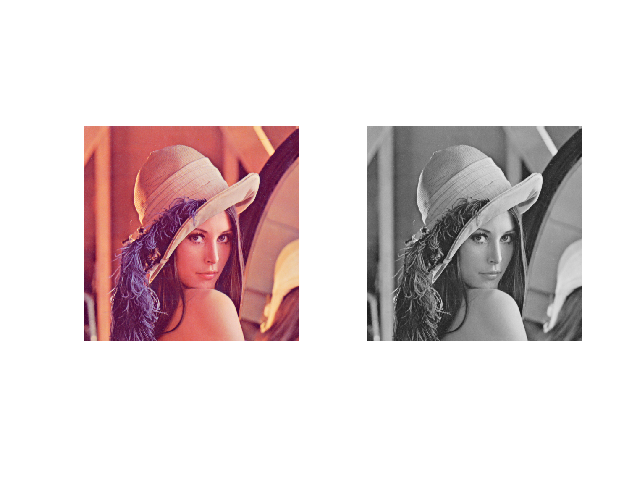

% Read the input image

%original_image = imread('city.jpg');
original_image = imread('Lenna.png');

gray_image = im2gray(original_image);

figure;
subplot(1, 2, 1);
imshow(original_image)
subplot(1, 2, 2);
imshow(gray_image)


gray_image = double(gray_image);

% average kernel
average_filter = fspecial('average',7); 
image_smooth = filter2(average_filter, gray_image); 

% Make a high-pass image:
image_highpass = gray_image - image_smooth; 
image_highboosted = gray_image + image_highpass * 2.;


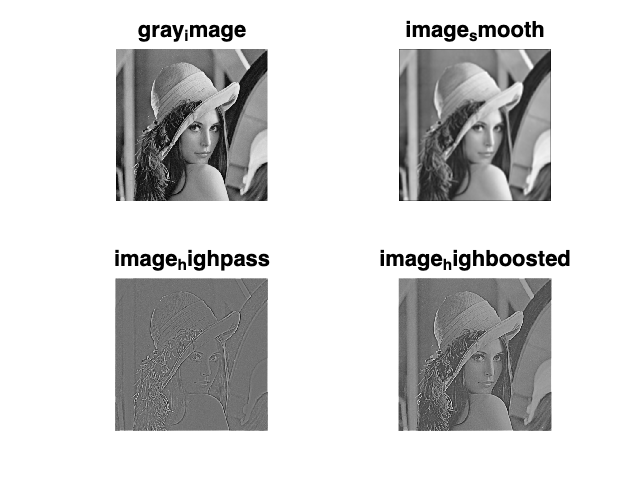

% plot the figure

figure;
subplot(2, 2, 1);
imshow(gray_image, [], "InitialMagnification", 'fit');
title('gray_image');
subplot(2, 2, 2);
imshow(image_smooth, [], "InitialMagnification", 'fit');
title('image_smooth');
subplot(2, 2, 3);
imshow(image_highpass, [], "InitialMagnification", 'fit');
title('image_highpass');
subplot(2, 2, 4);
imshow(image_highboosted, [], "InitialMagnification", 'fit');
title('image_highboosted');

% convolution

hp = (1/9) .* [-1 -1 -1; -1 8 -1; -1 -1 -1];

image_convolved = filter2(hp, gray_image); % perform convolution

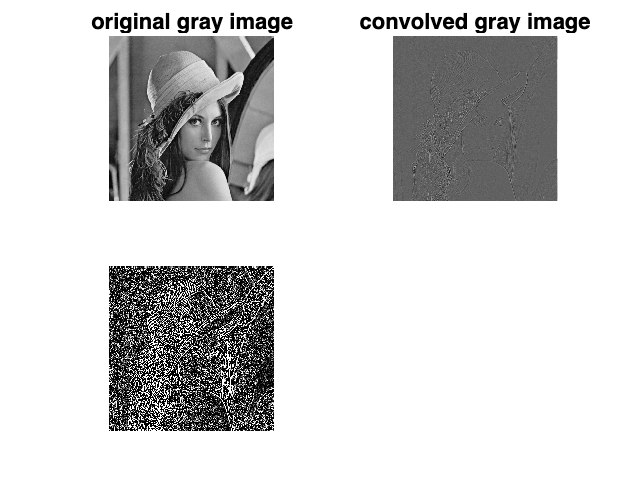

% plot the figure

figure;
subplot(2,2,1);
imshow(gray_image, [], "InitialMagnification", 'fit');
title('original gray image')
subplot(2,2,2);
imshow(image_convolved, [], "InitialMagnification", 'fit');
title('convolved gray image')
subplot(2,2,3);
imshow(image_convolved, [0,3], "InitialMagnification", 'fit');

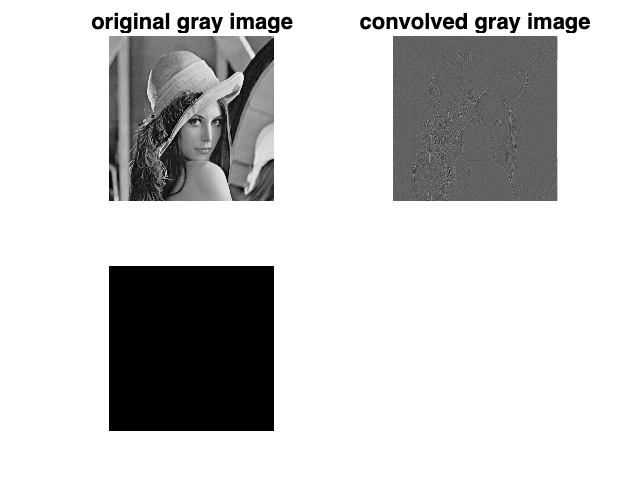

% threshold trying

% level = graythresh(image_convolved)
level = 230;

threshold_image = imbinarize(image_convolved,level);

imshow(threshold_image)

% imshowpair(image_convolved,threshold_image,'montage')